## Zestaw 4

Ad 1

    Generowanie losowego digrafu zespołu(n, p)

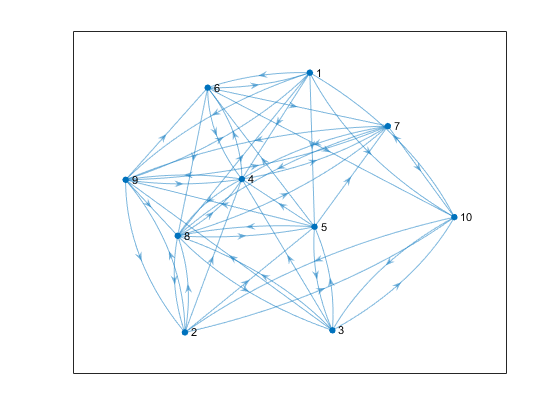

clear; close all; clc;
n = 10;
p = 0.5;
digraph1 = genRandDigraph(n, p);
% A = ones(n) - eye(n);
% digraph1 = Digraph(A);

plot(digraph1);

digraph1.getAdjacencyMatrix()

ans =      0     0     0     1     1     1     0     0     1     1
     0     0     0     1     1     0     0     1     1     1
     0     0     0     1     1     0     0     1     1     1
     0     0     0     0     0     1     1     1     1     0
     0     0     1     1     0     1     1     1     1     0
     1     0     0     1     0     0     1     1     0     1
     0     0     0     1     0     0     0     1     1     1
     1     1     1     1     1     0     1     0     0     0
     1     1     0     1     0     1     1     1     0     0
     1     1     1     0     0     0     0     0     0     0


Ad 2

    Wyznaczanie spójnych składowych algorytmem Kosaraju

comp = kosaraju(digraph1)

comp =      1     1     1     1     1     1     1     1     1     1


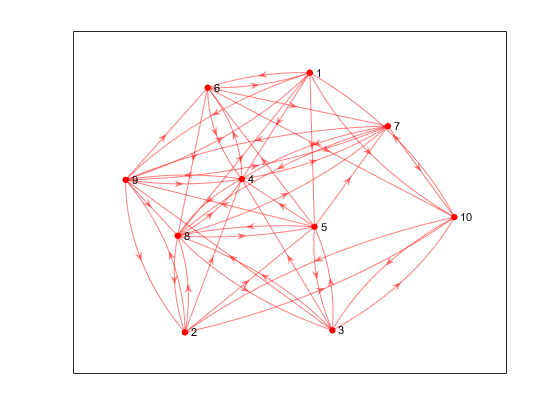

h = plot(digraph1);
nodes = digraph1.Nodes;
ncomp1 = nodes(comp==1);
for i=1:length(ncomp1)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp1(i));
    highlight(h,ncomp1(i),intersect(nbors, ncomp1),'EdgeColor','r');
end
highlight(h,ncomp1,'NodeColor','r');

highlight(h,nodes(comp==2),'NodeColor','g');
ncomp2 = nodes(comp==2);
for i=1:length(ncomp2)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp2(i));
    highlight(h,ncomp2(i),intersect(nbors, ncomp2),'EdgeColor','g');
end
highlight(h,nodes(comp==3),'NodeColor','m');
ncomp3 = nodes(comp==3);
for i=1:length(ncomp3)
    mdigraph = digraph1.getDigraph();
    nbors = successors(mdigraph,ncomp3(i));
    highlight(h,ncomp3(i),intersect(nbors, ncomp3),'EdgeColor','m');
end

Ad 3 i 4

    Algorytm Bellmana-Forda oraz Johnsona

if max(comp)==1
    noEdges = length(digraph1.Edges(1,:));
    weights = randi(10,[1, noEdges]);

Aby uniknąć ujemnych cyklów liczba krawędzi z wagami mniejszymi jest znacząco mniejsza od liczby krawędzi z wagami dodatnimi

    noEdgesMinus= round(sqrt(n));
    for i=1:noEdgesMinus
        weights(randi(noEdges)) = -randi(5);
    end
    digraph1.Edges = [digraph1.Edges; weights];
    h = plot(digraph1.getDigraph(),'EdgeLabel',weights);
    [D, P] = johnson(digraph1)
    

Zaznaczanie wybranej ścieżki

D =      0     9     6     8     6     5     5     4     8     4
     0     0     2     2     4     5     3     0     4     3
    -1     6     0     5     3     4     2    -1     3     1
     5    12     6     0     8     7     2     4     9     7
    -2     6     0     2     0     3    -1    -2     2     1
     4    11     5     4     7     0     1     3     8     6
     3    10     4     3     6     8     0     2     7     5
     1     8     2     6     4     6     3     0     5     3
    -4     4    -2     2     0     1    -1    -4     0    -1
     5     5     7     7     9    10     8     5     9     0


P =      0    10     8     1     1     1     5     9     5     1
     9     0     8     2     8     1     5     9     2     3
     9    10     0     7     8     1     5     9     3     3
     9    10     8     0     8     4     4     7     4     3
     9    10     8     7     0     5     5     9     5     3
     9    10     8     7     8     0     6     7     7     3
     9    10     8     7     8     1     0     7     7     3
     9    10     8     7     8     1     5     0     3     3
     9    10     8     7     8     1     5     9     0     3
     9    10     8     2     8     1     5     9     2     0


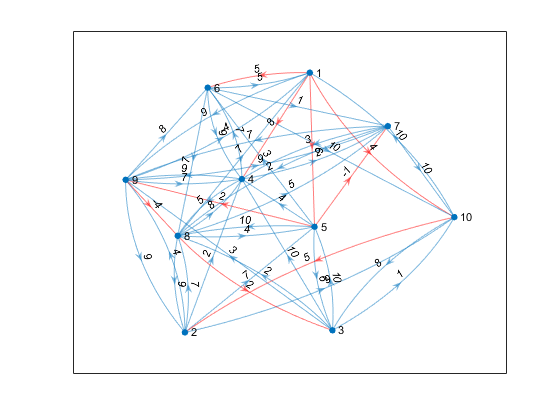

    noPath = 1;
    path = P(noPath, :);
    for i=1:n
        if i==noPath
            continue;
        end
       highlight(h,path(i),i,'EdgeColor','r'); 
    end
else
    error("Digraf nie jest silnie spójny! Proszę spróbować inny")
end